clc
clear all 
close all
%%% This example is an illustarion of the application of LDA on data
%%% generated using Gaussian mixture models or uniform mixuture models with
%%% different dimensionalities.
%%% PDF parameters are selected first, then data is generated from a
%%% mixture of PDFs. projection vectors are later generated by performing LDA
%%% on generated data, then data is projected on the projection vector and plotted.

%%% Gaussian distribution case %%%
%% Generate two datasets from two different gaussian distributions/categories

%% 1st data category
N1=1000; %specify number of samples of each category
pdfParameters.Mean=[5;1];% normal distribution mean
pdfParameters.Cov=[1 -1.5; -1.5 3];% normal distribution Covariance
pdfParameters.type='Gaussian';
n = size(pdfParameters.Mean,1); % Determine data dimensionality

%generate N points of random samples from pdf N(pdfParameters.Mean,pdfParameters.Cov))
x1=generateRandomSamples(N1,n,pdfParameters,0);


%% 2nd data category
clear pdfParameters n
N2=1300; %specify number of samples of each category
pdfParameters.Mean=[-1;-3];% normal distribution mean
pdfParameters.Cov=[5 -.5; -.5 10];% normal distribution Covariance
pdfParameters.type='Gaussian';
n = size(pdfParameters.Mean,1);% Determine data dimensionality

%generate N points of random samples from pdf N(pdfParameters.Mean,pdfParameters.Cov))
x2=generateRandomSamples(N2,n,pdfParameters,0);

x = [x1,x2]; labels = [ones(1,N1),2*ones(1,N2)];
%% Determine LDA vector and data projected on it
[w,y]=performLDA(x,labels);

y =     4.4003    5.9514    4.9677    5.6746    6.0288    5.2840    5.3447    4.7355    4.6634    4.7025    4.6414    5.4359    4.4626    4.6657    5.6801    4.4889    4.7234    5.0626    4.5911    4.6686    4.5492    4.7100    4.3168    4.7608    5.4760    4.8725    4.6507    5.3946    4.8180    4.2784    4.0650    4.3356    4.5730    4.5699    4.7420    4.8793    5.6583    5.0035    5.0026    4.5419    4.5922    5.3455    5.1199    5.3155    5.0661    3.7784    5.6640    5.5847    5.6372    4.4741


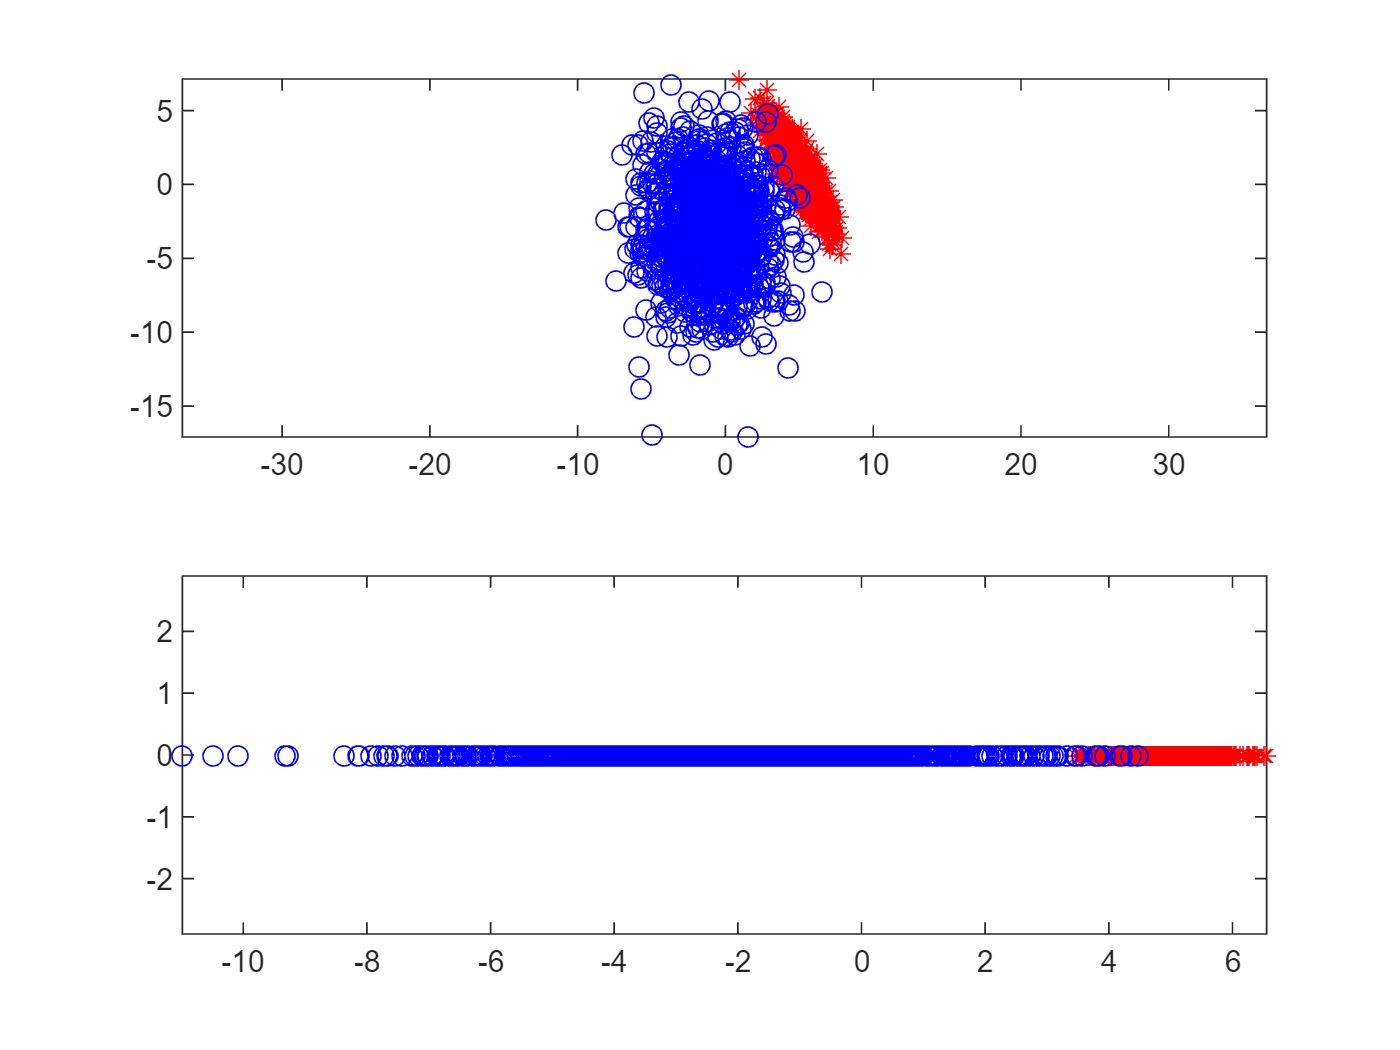


% find where each labeled data is projected
y1 = y(find(labels==1)); y2 = y(find(labels==2));
%% plot 
% Plot the data before and after linear projection
figure(1),
subplot(2,1,1), plot(x1(1,:),x1(2,:),'r*'); hold on;
plot(x2(1,:),x2(2,:),'bo'); axis equal, 
subplot(2,1,2), plot(y1(1,:),zeros(1,N1),'r*'); hold on;
plot(y2(1,:),zeros(1,N2),'bo'); axis equal,




%%%Uniform Distributions case %%%
%% Generate two datasets from two different uniform distributions categories

%% 1st data category
clear pdfParameters n
N1=1000; %specify number of samples of each category
%store parameters in a structure
pdfParameters.a=[-5 ;1];%uniform distribution lower endpoints of the x and y axis
pdfParameters.b=[-1; 5 ] ; %uniform distributions higher endpoint of the x and y axis
pdfParameters.Scale=(pdfParameters.b-pdfParameters.a)/2;
pdfParameters.Mean=(pdfParameters.a+pdfParameters.b)/2;
pdfParameters.type='Uniform';
n = size(pdfParameters.a,1); % Data dimensionality


%generate N points of random samples from pdf N(pdfParameters.Mean,pdfParameters.Cov))
x1=generateRandomSamples(N1,n,pdfParameters,0);


%% 2nd data category
clear pdfParameters n
N2=1300; %specify number of samples of each category
%store parameters in a structure
pdfParameters.a=[1 ;5];%uniform distribution lower endpoints of the x and y axis
pdfParameters.b=[5; 10 ] ; %uniform distributions higher endpoint of the x and y axis
pdfParameters.Scale=(pdfParameters.b-pdfParameters.a)/2;
pdfParameters.Mean=(pdfParameters.a+pdfParameters.b)/2;
pdfParameters.type='Uniform';
n = size(pdfParameters.a,1); % Data dimensionality

%generate N points of random samples from pdf N(pdfParameters.Mean,pdfParameters.Cov))
x2=generateRandomSamples(N2,n,pdfParameters,0);

x = [x1,x2]; labels = [ones(1,N1),2*ones(1,N2)];
%% Determine LDA vector and data projected on it
[w,y]=performLDA(x,labels);

y =    -1.0530   -2.1507   -1.8833   -0.1094   -0.6196   -0.2725   -0.8426   -0.3939   -1.2839   -1.5397   -0.9488   -0.2252    0.5874   -0.4681   -0.6188   -1.8189   -0.5344   -0.8675   -2.0944   -0.0362   -1.7109   -1.9950   -0.9150   -1.9332    1.5280   -2.4469   -1.3451   -2.6461   -1.5500   -1.8175   -1.1675   -0.9843   -2.6407   -1.2138   -2.4408   -2.2550   -2.5566   -0.3433   -2.4595    0.1453   -3.3835   -1.0937    1.0323   -0.2645   -1.1586   -2.5840   -3.0155    1.0482   -1.1542   -0.2796


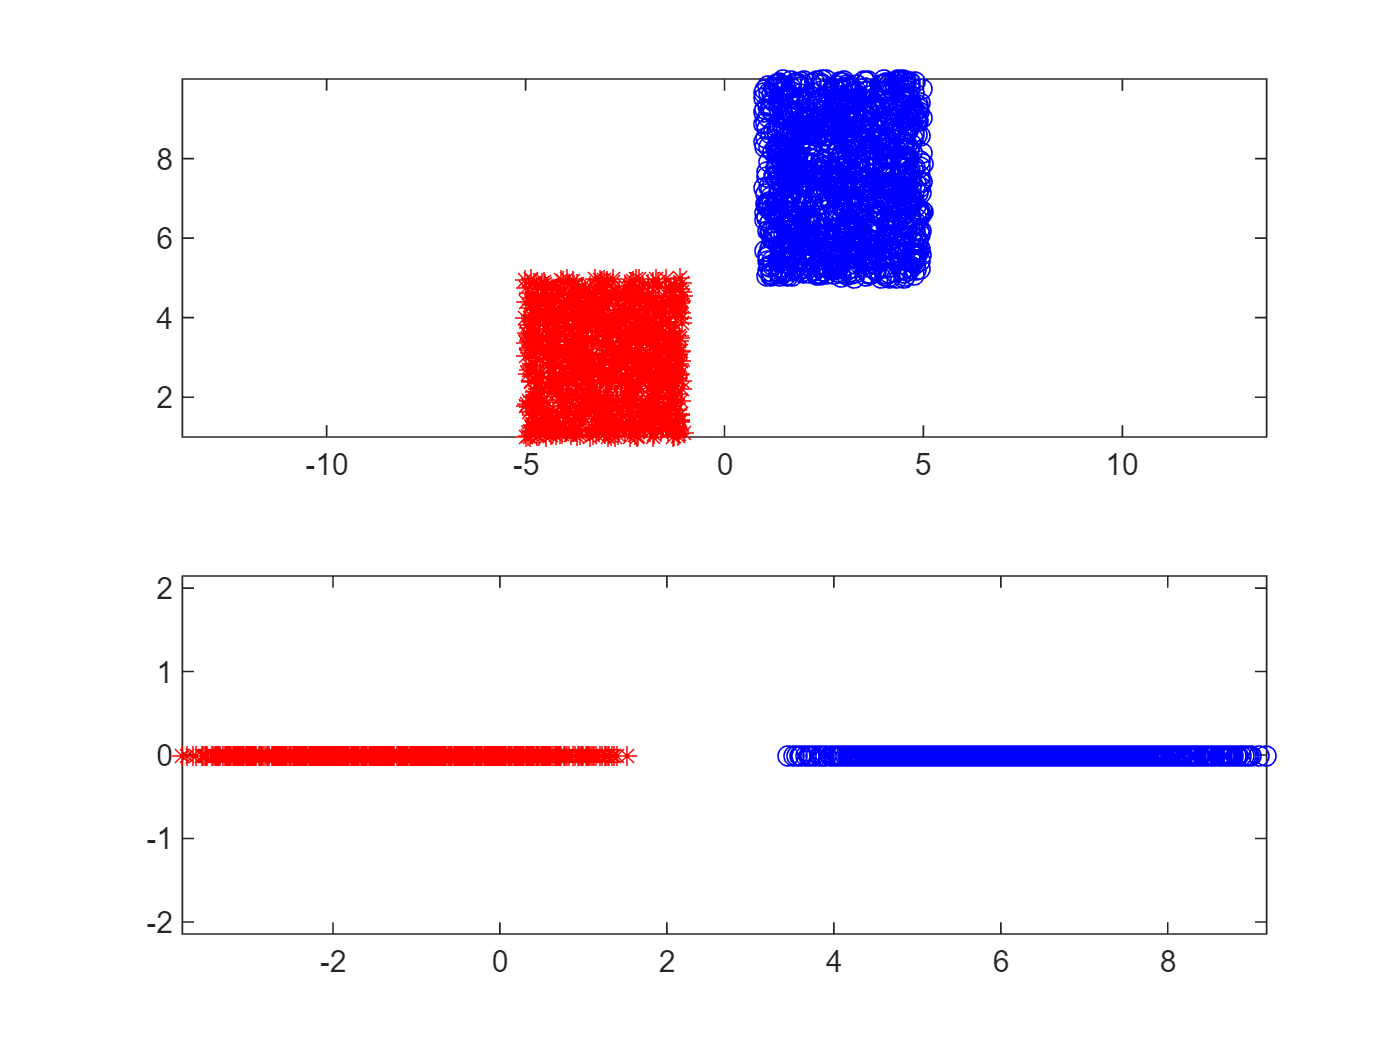


% find where each labeled data is projected
y1 = y(find(labels==1)); y2 = y(find(labels==2));
%% plot 
% Plot the data before and after linear projection
figure(2),
subplot(2,1,1), plot(x1(1,:),x1(2,:),'r*'); hold on;
plot(x2(1,:),x2(2,:),'bo'); axis equal, 
subplot(2,1,2), plot(y1(1,:),zeros(1,N1),'r*'); hold on;
plot(y2(1,:),zeros(1,N2),'bo'); axis equal,